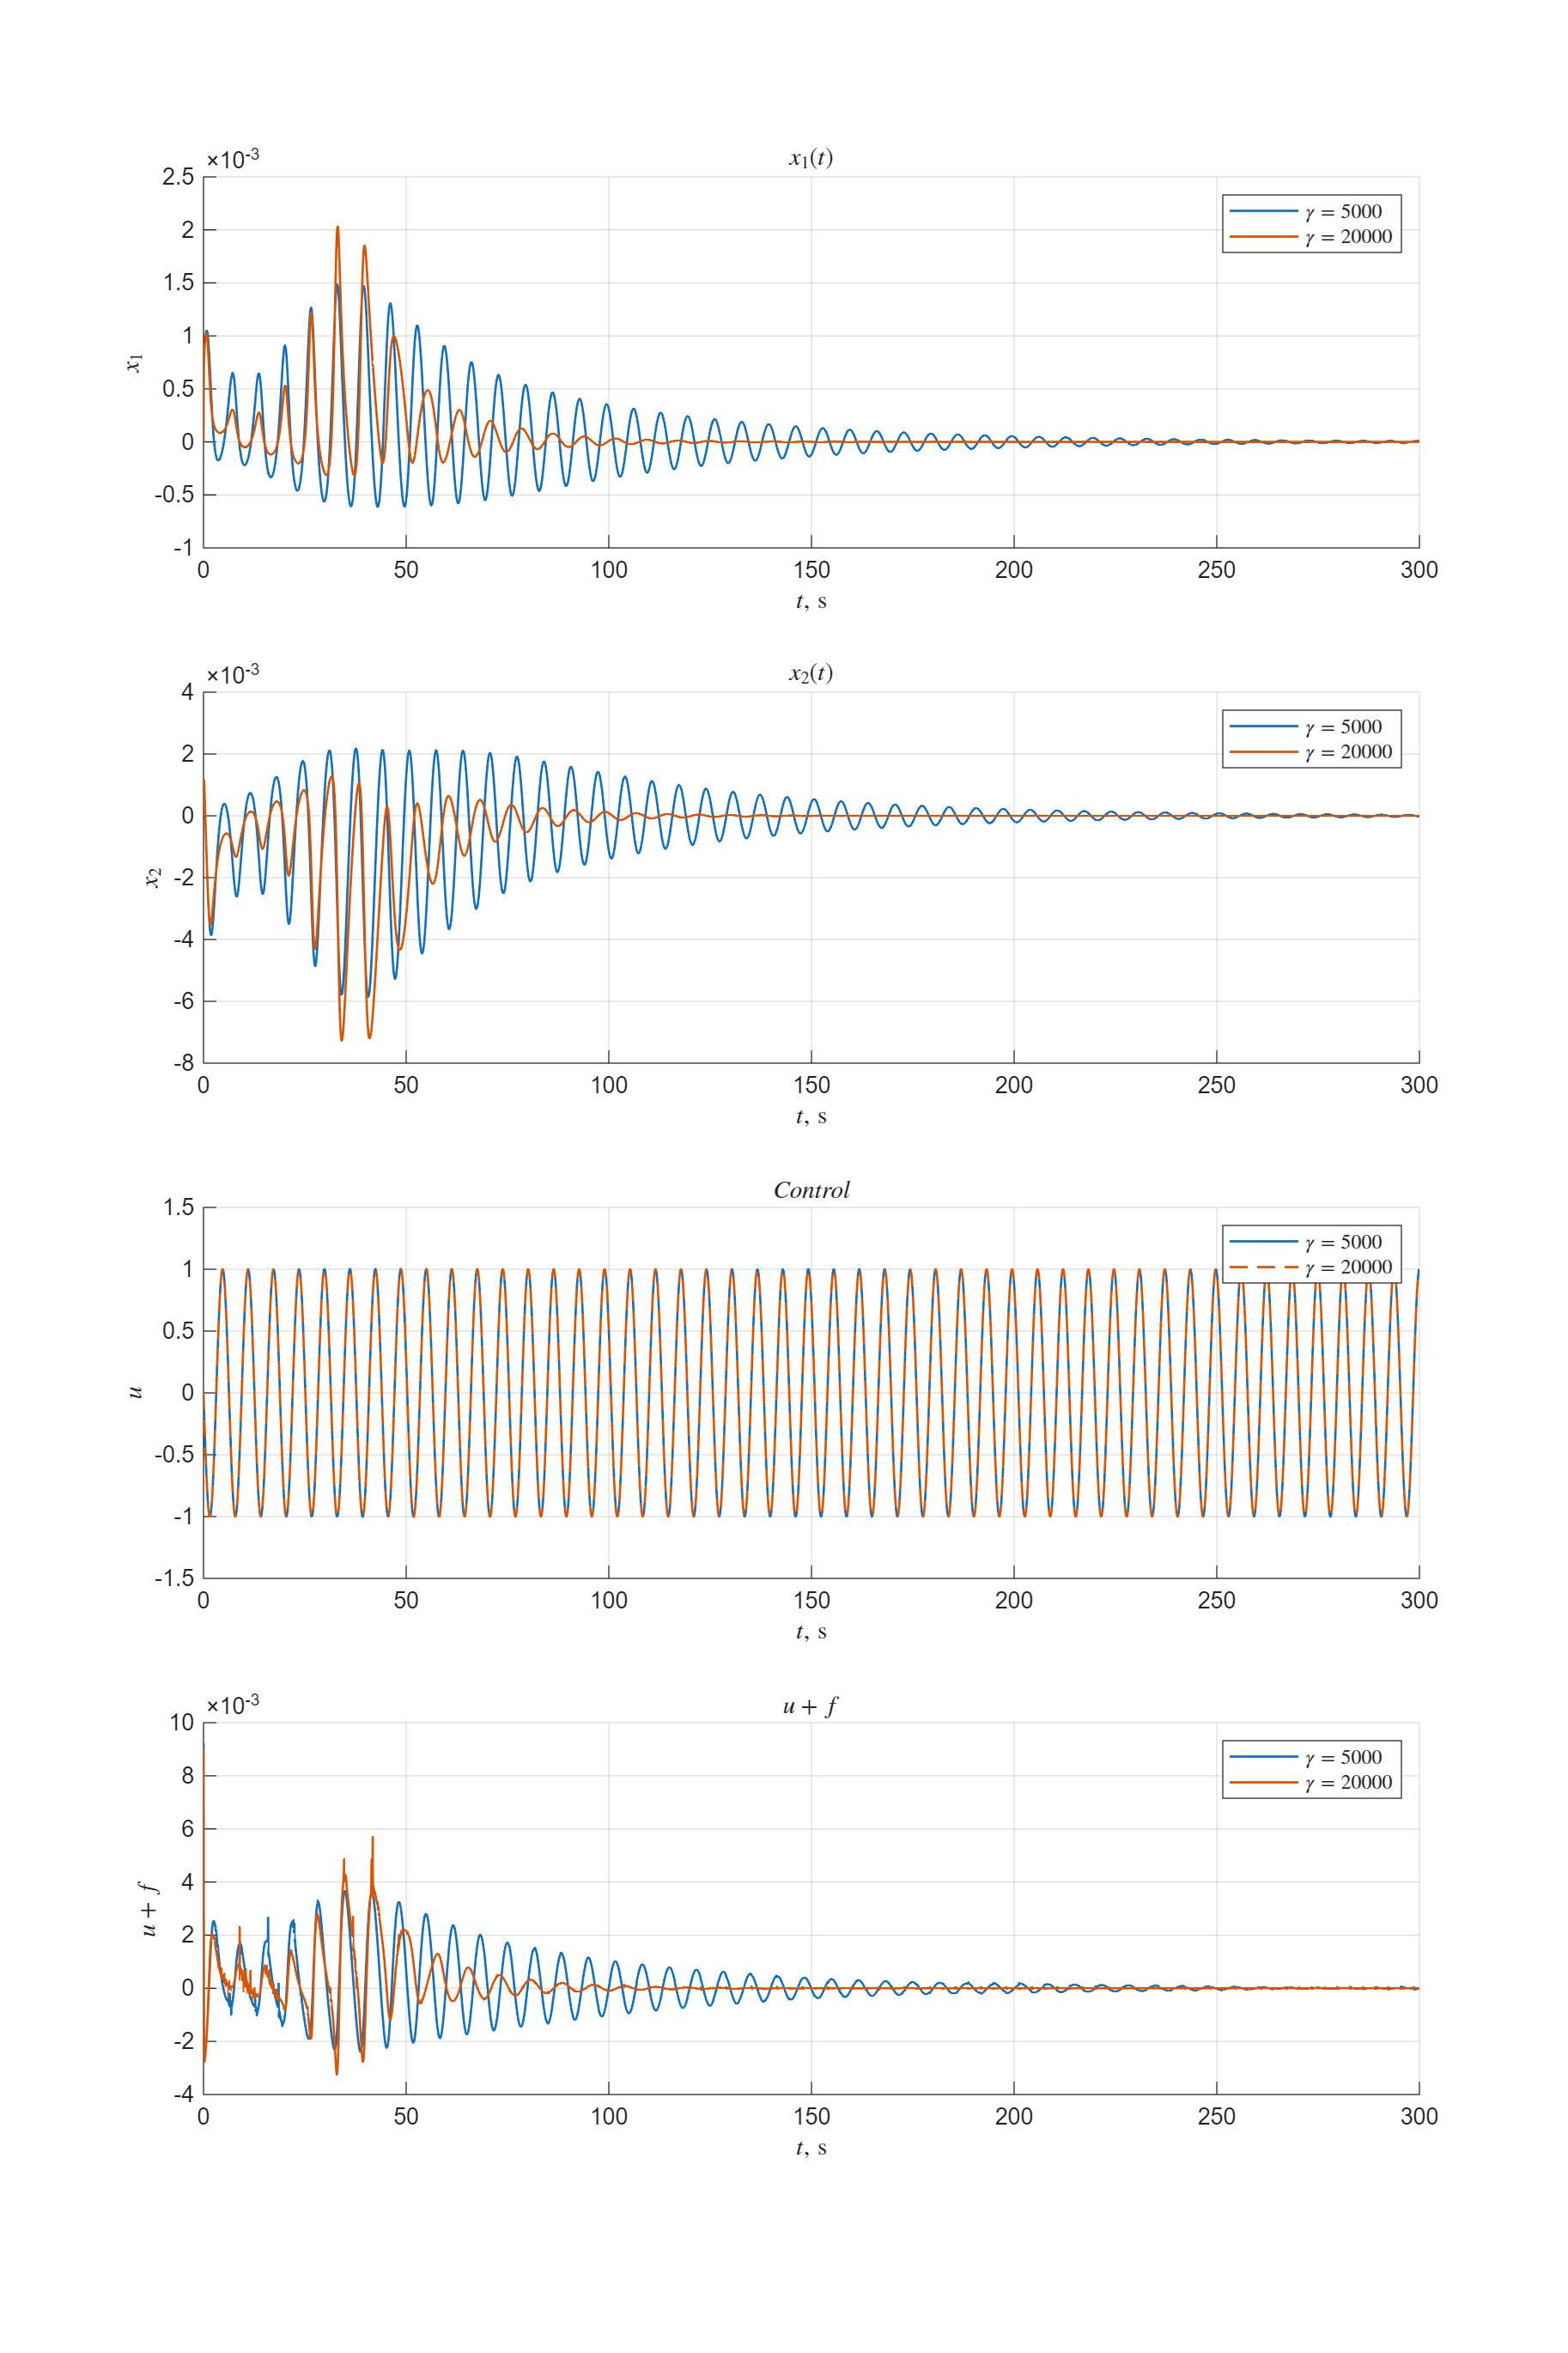

A = [3 1; 1 1];
b = [1; 2];
d = b;
kf1 = 0.2;
kf0 = 0.01;
K = [434.225220821837 -178.650599773935];
Q = eye(2);
AM = A - b*K;
P = lyap(AM.', Q);

gamma1 = 5000;
gamma2 = 20000;
simtime = 300;

gamma = gamma1;
out = sim("lab11.slx", simtime);
x1 = out.x.Data;
u1 = out.u.Data;
t1 = out.x.Time;
uf1 = out.uf.Data;

gamma = gamma2;
out = sim("lab11.slx", simtime);
x2 = out.x.Data;
u2 = out.u.Data;
t2 = out.x.Time;
uf2 = out.uf.Data;

f = figure;
f.Position = [100 100 1200 1800];

labels = { ...
    sprintf('$\\gamma=%g$', gamma1), ...
    sprintf('$\\gamma=%g$', gamma2)};

for i = 1:2
    subplot(4,1,i);
    hold on;
    plot(t1, x1(:,i), LineWidth=1);
    plot(t2, x2(:,i), LineWidth=1);
    hold off;

    legend(labels, Interpreter="latex");
    grid on;
    title(sprintf('$x_%d(t)$', i), Interpreter="latex");
    xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
    ylabel(sprintf('$x_%d$', i), Interpreter="latex");
end

subplot(4,1,3);
hold on;
plot(t1, u1, LineWidth=1);
plot(t2, u2, LineStyle="--", LineWidth=1);
hold off;

legend(labels, Interpreter="latex");
grid on;
title("$Control$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u$", Interpreter="latex");

subplot(4,1,4);
hold on;
plot(t1, uf1, LineWidth=1);
plot(t2, uf2, LineWidth=1);
hold off;

legend(labels, Interpreter="latex");
grid on;
title("$u+f$", Interpreter="latex");
xlabel("$t,\;\mathrm{s}$", Interpreter="latex");
ylabel("$u+f$", Interpreter="latex");

folder = "C:/Users/Nickolay/Desktop/ITMO-courses/7_term/Adaptive_and_robust_control/lab11/tex/images/";
exportgraphics(f, fullfile(folder, "lab11.png"), Resolution=600);